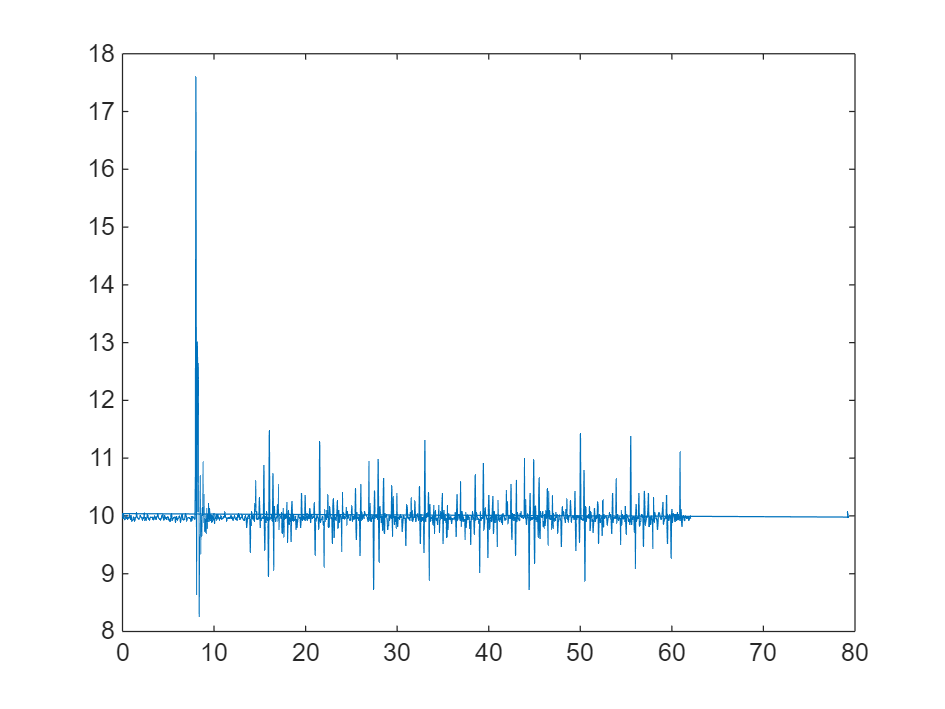

ts = 0.0495

std_ts = 6.2193e-04

fs = 20.1919

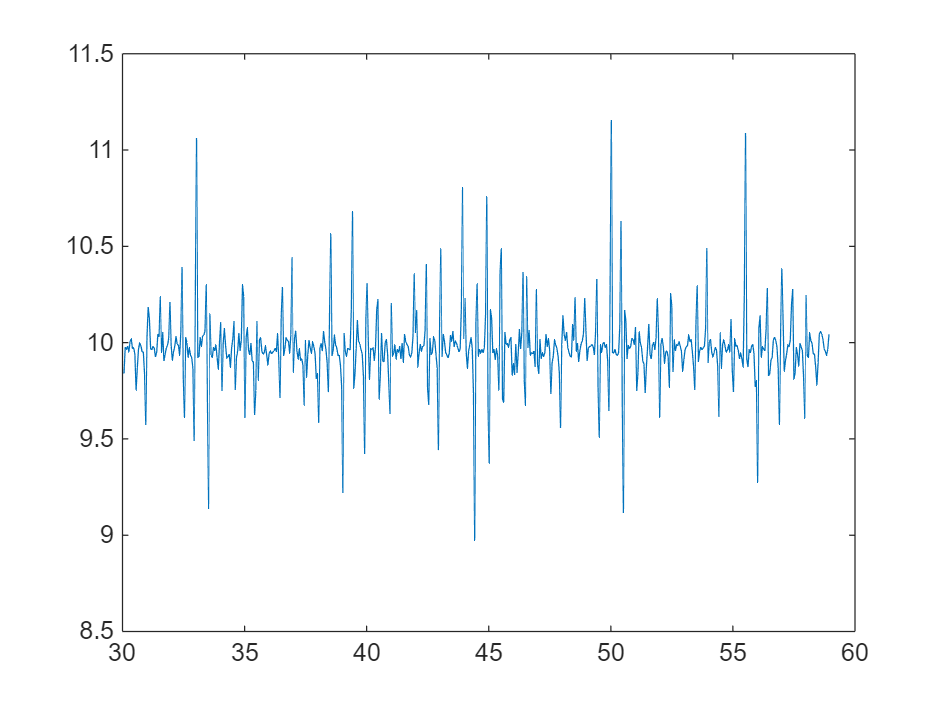

clc
clear
close all

voltage = 5.5;

data2plot = [];
data2compare = cell(1,length(voltage));

for i = 1:length(voltage)

    acc_file = strcat("sync_acc_",num2str(voltage(i)),"V.csv");

    raw_data = readtable(acc_file);
    raw_data(1,:) = [];
    raw_data(end,:) = [];


    raw_time = raw_data{:,1}./1000;
    long_data = raw_data{:,8};

    figure;
    plot(raw_time,long_data)

    if voltage(i) == 2
        time_idx = (raw_time > 90) & (raw_time < 130);

    elseif voltage(i) == 5
        time_idx = (raw_time > 20) & (raw_time < 50);
    else
        time_idx = (raw_time > 30) & (raw_time < 59);

    end

    time = raw_time(time_idx);
    data = long_data(time_idx);



    time_diff = time(2:end) - time(1:end-1);
    ts = mean(time_diff)
    std_ts = std(time_diff)
    fs = 1./ts

    rs_time = 0:ts:350;

    zero_ind = find(time_diff == 0);
    time(zero_ind) = [];
    data(zero_ind) = [];

    [~,idx_end] = min(abs(rs_time - time(end)));
    [~,idx_stt] = min(abs(rs_time - time(1)));


    rs_time  = rs_time(idx_stt:idx_end);
    rs_data = interp1(time,data,rs_time);

    rs_time(1) = [];
    rs_data(1) = [];

    rs_time(end) = [];
    rs_data(end) = [];

    figure;
    plot(rs_time,rs_data)

    % Low pass to try to remove noise

    cutoff_freq = 8;    % Cutoff frequency in Hz
    filter_order = 4;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'low');
    lp_data= filtfilt(b, a, rs_data);

    figure;
    plot(rs_time,lp_data)

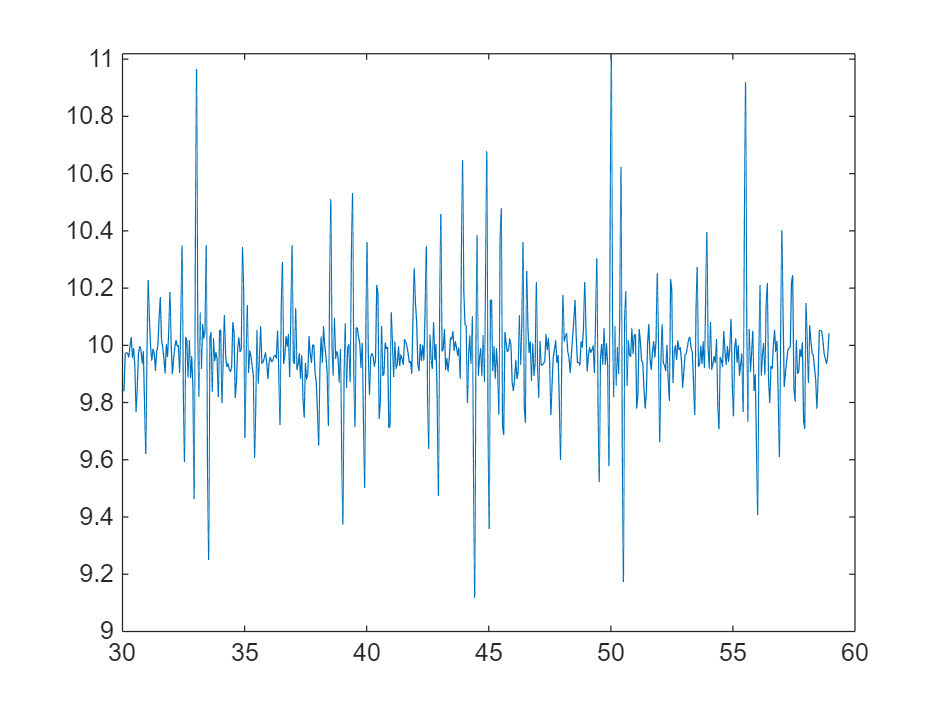

    % High pass to try to remove baseline


    cutoff_freq = 1;    % Cutoff frequency in Hz
    filter_order = 4;    % Filter order (adjust as needed)

    % lpf = designfilt('lowpassiir', ...
    %     'FilterOrder', filter_order, ...
    %     'HalfPowerFrequency', cutoff_freq, ...
    %     'SampleRate', fs, ...
    %     'DesignMethod', 'butter');

    [b, a] = butter(filter_order, cutoff_freq/(fs/2), 'high');
    hp_data= filtfilt(b, a, lp_data);

    % smooth_data = smooth(hp_data,5);
    smooth_data = hp_data;

    % pre_smooth_data = smooth(pre_smooth_data,'sgolay',4)';



    % magnitude
    RMS = sqrt(mean(hp_data.^2))

    crop_data = smooth_data((rs_time-36 >0)&(rs_time-36 < 16));
    crop_time = rs_time((rs_time-36 >0)&(rs_time-36 < 16));

    % p2p
    [pk_vals, pk_locs] = findpeaks(crop_data, crop_time,'MinPeakProminence', 0.075);
    [tr_vals_neg, tr_locs] = findpeaks(-smooth_data, rs_time,'MinPeakProminence', 0.1);
    tr_vals = -tr_vals_neg;

    act_time = 34:0.005:52;
    act_time(end) = [];
    act_time = act_time+0.014;
    single_act_data = [zeros(1,67),ones(1,33)]*0.4 - 0.2;
    act_data = repmat(single_act_data,1,36);

    figure;
    plot(rs_time-36,smooth_data,'LineWidth',1.25)
    hold on
    plot(act_time-36,act_data);
    plot(pk_locs-36,pk_vals,'*')
    hold off
    xlim([0 16])
    xlabel('Time (s)')
    ylabel('acceleration (m/s^2)')
    legend('ACC data','Activation signal')

    rms_pk = sqrt(mean(pk_vals.^2))


RMS = 0.1732

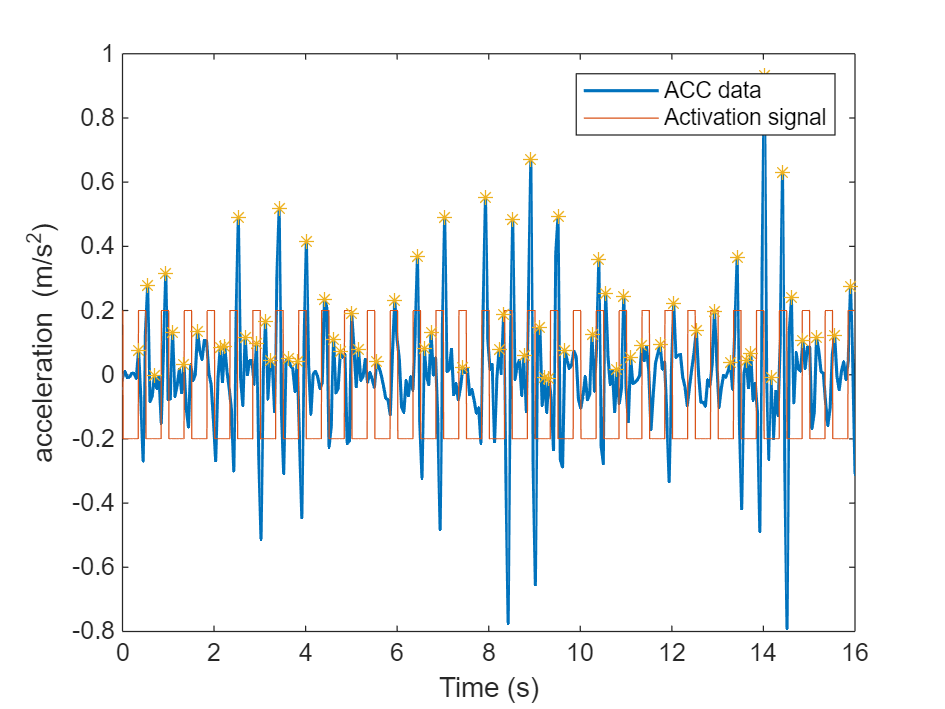

rms_pk = 0.2744


    if tr_locs(1) < pk_locs(1)
        tr_locs(1) = []; tr_vals(1) = [];
    end

    N = min(numel(pk_locs), numel(tr_locs));
    pk_locs = pk_locs(1:N);
    pk_vals = pk_vals(1:N);
    tr_locs = tr_locs(1:N);
    tr_vals = tr_vals(1:N);

    p2p = pk_vals - tr_vals;
    mean_p2p = mean(p2p)
    std_p2p = std(p2p)

    data2save = [voltage(i),RMS,mean_p2p,std_p2p];
    data2plot = [data2plot;data2save];
    data2compare{i} = p2p;

end

mean_p2p = 0.3965

std_p2p = 0.2574

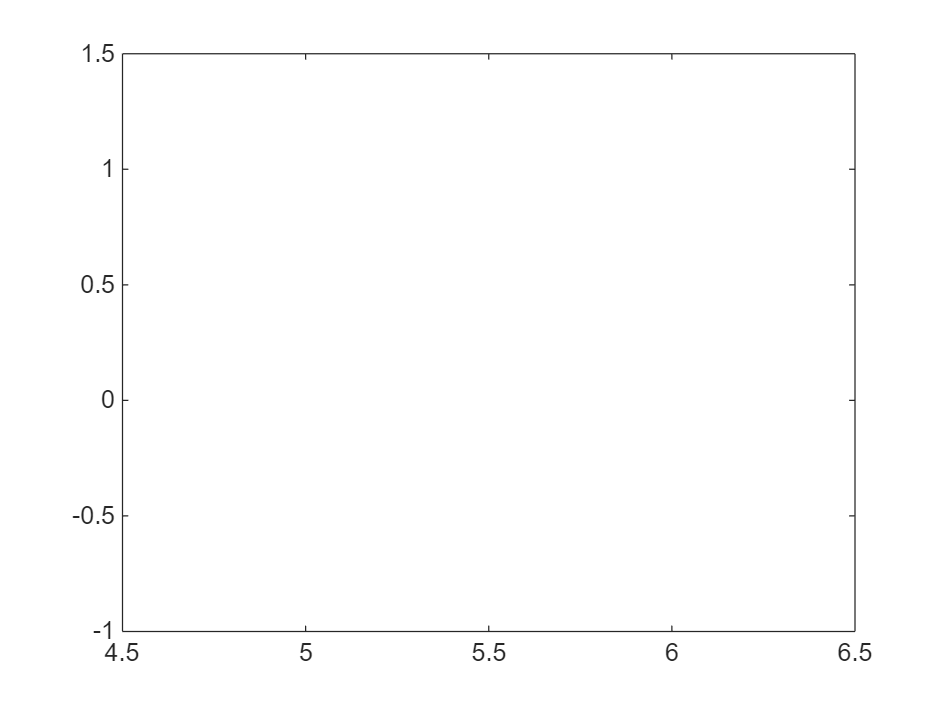

figure;
plot(data2plot(:,1),data2plot(:,2))

figure;
plot(data2plot(:,1),data2plot(:,3))

figure;
plot(data2plot(:,1),data2plot(:,4))